% ______ FFT ______
close all
clearvars
% ============================================

im = imread('bld.tif');
im = im2double(im);

F = fft2(im);
ABS = abs(F);

imshow(ABS)

imshow(log(1+ABS), []), title('Mag')

% FFTshift

F = fftshift(fft2(im));
ABS = abs(F);

imshow(ABS)
Img = log(1+ABS);

imshow(log(1+ABS), []), title('Mag-shift')

org = ifft2(ifftshift(F));
imshow(org)

% Phase
close all
clearvars
% ============================
im = imread('Woman.jpg');
im = rgb2gray(im);
im = im2double(im);
imshow(im)

% Phase

F = fft2(im);

Phase = angle(F);

imshow(ifft2(exp(i*Phase)), [])

imshow(log10(1+ifft2(abs(F))), [])

% _______________________ FILTERING ____________________________
close all
clearvars
% =======================================

img = imread('a.tif');
img = im2double(img);

% ---------------------------------------

imshow(img), title('Original Image')

[r, c] = size(img);

uc = floor(c/2)+1;
vc = floor(r/2)+1;

Mask = ones(r, c);
D0 = 10;

for i = 1: r
    for j = 1:c
        D = sqrt((j - vc).^2 + (i - uc).^2);
        if D < D0
            Mask(i, j) = 0;
        end
    end
end

F = fftshift(fft2(img));

G = F .* Mask;

imshow(Mask), title('Mask')
imshow(G), title('Filtered-freq')

Rec = ifft2(ifftshift(G));
imshow(Rec), title('Filtered image')
% -------------------------------
LP = 1 - Mask;
G = F .* LP;

imshow(Mask), title('Mask')
imshow(G), title('Filtered-freq')

Rec = ifft2(ifftshift(G));
imshow(Rec), title('Filtered image')

% -------------------------------------------
% _______________ Butterworth-low pass_______________
n = 2; 
D0 = 10;
BL_filt=zeros(r,c);

for i=1:r
   for j=1:c
      BL_filt(i,j)=1./((1+sqrt((j-uc)^2+(i-vc)^2)./D0)).^2*n;
   end
end

F = fftshift(fft2(img));
Filter = F .* BL_filt;
Output_BL = ifft2(ifftshift(Filter));
imshow(Output_BL, []), title('BL')

% --------------------------------------------
% ______________________Gaussian____________________
D0 = 10;
GL_filt=zeros(r,c);
for i=1:r
   for j=1:c
      GL_filt(i,j)=exp(-1.*((j-uc)^2+(i-vc)^2)./(2.*D0^2));
   end
end

F = fftshift(fft2(img));
Filter = F .* GL_filt;
Output_G = ifft2(ifftshift(Filter));
imshow(Output_G, []), title('Gaussian')


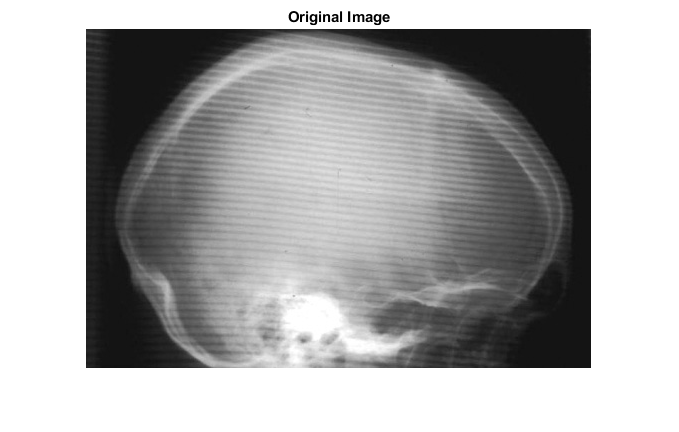

%____________ Periodic Noise Filtering _____________
close all
clearvars
% ===============================================

im = imread('skull.jpg');
im = im2double(im);
[r, c] = size(im);

imshow(im), title('Original Image')

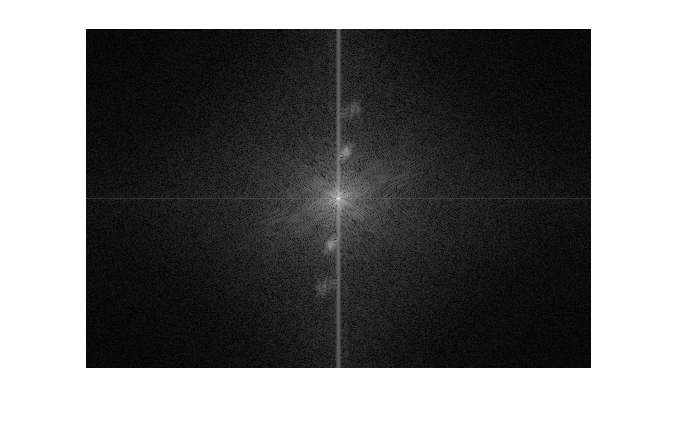


F = fftshift(fft2(im));
imshow(log(1+abs(F)), [])

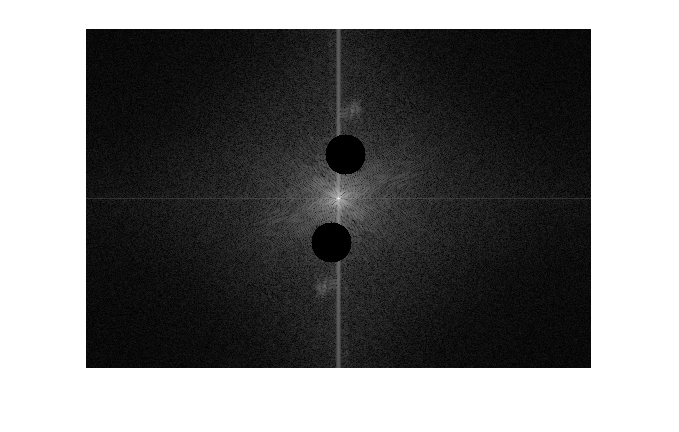


filt = NOTCH(r, c, 260, 126, 20);
imshow(log(1+abs(filt.*F)), [])

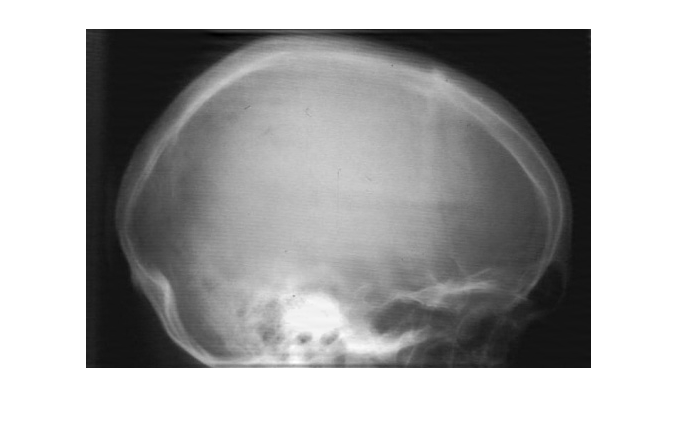

img = ifft2(ifftshift((filt .* F)));
imshow(img, [])

function filt = NOTCH(R, C, U0, V0, D0)
filter = ones(R, C);
for i = 1:R
    
    for j = 1:C
       if sqrt((j-U0)^2+(i-V0)^2) <= D0
           filter(i, j) = 0;
       end
    end
end

filt = filter.*rot90(filter, 2);
end